# **zProof of Concept**

**Notes: **It needs Yalmip and OSQP. Yalmip should install himself automatically both on Windows and Linux. OSQP should automatically install on Linux, if there are any problems read the README. On Windows you need to install OSQP yourself.

There are TONs of other parameters and configuration you can tune and adapt, but atm you need to search them yourself.

clc;
clear variables;
terminate(pyenv)
%pyenv(Version='/scratch/msc23h12/python/bin/python3',ExecutionMode='OutOfProcess');

## **Initialization**

%% INIT

% Instantiate main Class:
hpc = hpc_lab;

MAY be NOT Observable!
Size: 54800 bytes



% Core number
hpc.Nc = 9;

[TM] Remember to change Nh, Nv, epos, the parameter deviation vector, and the floorplan accordingly



% Rows and Columns
hpc.Nv = 3;

[TM] Remember to change Nh, epos, and the floorplan accordingly


hpc.Nh = 3;

[TM] Remember to change Nv, epos, and the floorplan accordingly



% Number of Voltage Domains
hpc.vd = hpc.Nc;

% How the cores are distributed per domain
%hpc.VDom = ... ;
% Alternatively
hpc.default_VDom_config();

% Default Floorplan and Parameter deviation vector
hpc.default_floorplan_config();
hpc.create_model_deviation();

%Decide simulation frequency (discrete timing)
hpc.Ts = 5e-5;

%Decide total simulation time
hpc.tsim = 2;

%Presence/Absence of sensor noise:
hpc.sensor_noise = 1;

%Thermal model version
hpc.model_ver = 0;

#### After the configuration of the Thermal Model, run the model creation & others

hpc.model_init();

MAY be NOT Observable!


hpc.create_core_pw_noise();

#### Choose targets

% Initial Temperature condition
hpc.t_init = hpc.temp_amb*ones(hpc.Ns,1);

%Input maximum frequency
hpc.Ts_target;

tt = min(ceil(hpc.tsim / hpc.Ts_target)+1, (hpc.tsim/1e-4+1));

% Target Frequency Trajectory
hpc.frtrc = 3.45 * ones(tt, hpc.Nc);

%Target Power Budget
hpc.tot_pw_budget = 450/36*hpc.Nc*ones(tt,1);
tu = ceil(tt/4);
hpc.tot_pw_budget(tu+1:2*tu) = 2*hpc.Nc;
hpc.tot_pw_budget(2*tu+1:3*tu) = 5*hpc.Nc;
hpc.tot_pw_budget(3*tu+1:3*tu+ceil(tu/2)) = 3*hpc.Nc;
hpc.tot_pw_budget(3*tu+ceil(tu/2)+1:end) = 8*hpc.Nc;
hpc.quad_pw_budget = 450/36*hpc.Nc*ones(2,hpc.vd);

%Others, TODO
hpc.min_pw_red = 0.6;

#### After all the configurations are done, running the checks:

hpc.anteSimCheckTM();
hpc.anteSimCheckLab();
hpc.anteSimCheckPM();

### **Generate Workload trace:**

%Probability of each workload type [idle, int, float, mem, vec]
hpc.wl_prob = [0.0345 0.3448 0.3448 0.2414 0.0345];

%Minimum execution time (us) of each workload type
hpc.wl_min_exec_us = [510 100 100 480 520];	

%Mean execution time (us) of each workload type
hpc.wl_mean_exec_us = [520e2 210e1 180e1 560e2 1.2e6/1e1];

%Generate it
hpc.wltrc = hpc.generate_wl_trace(hpc.Nc, hpc.tsim, 0);


## **SotA / CP MPC - no warm starting**

ctrl = cp_mpc;
ctrl.save_solver_stats = true;
ctrl.C = eye(hpc.Ns);

%Controller frequency (s)
ctrl.Ts_ctrl = 1e-3;
ctrl.Nhzn = 2;

%Robust Margins for T and P
ctrl.Cty = zeros(ctrl.Nhzn, hpc.Nc);
ctrl.Ctu = zeros(ctrl.Nhzn, hpc.Nc);

%Reference Tracking Objective Matrix
R_coeff = 10;
ctrl.R = R_coeff*eye(hpc.Nc);

%Others
ctrl.R2 = zeros(hpc.Nc);
ctrl.Q = zeros(hpc.Ns);

Optimizer object with 33 inputs (4 blocks) and 31 outputs (2 blocks). Solver: OSQP


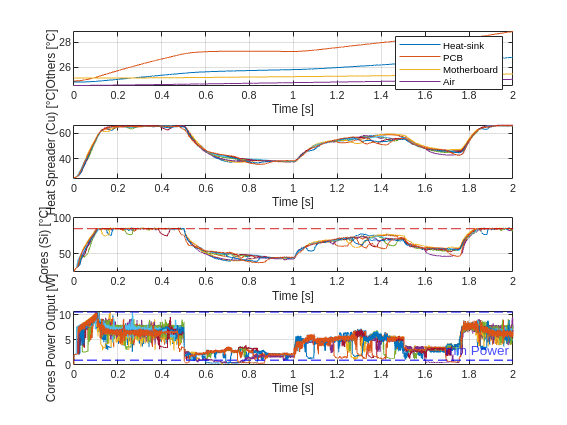

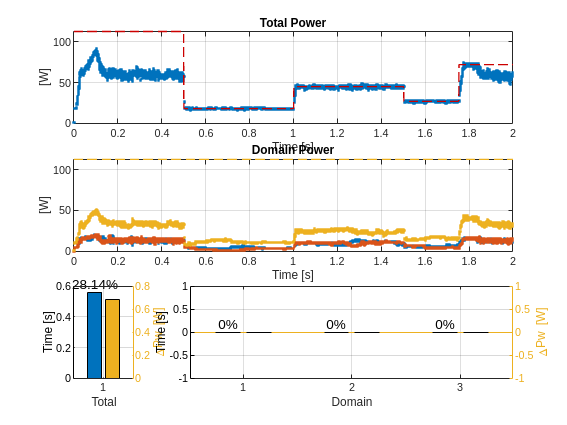

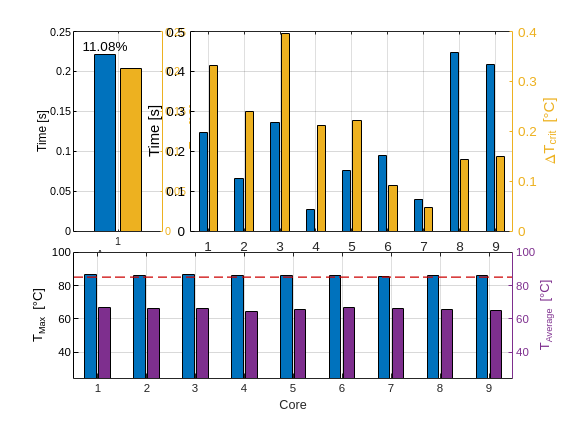

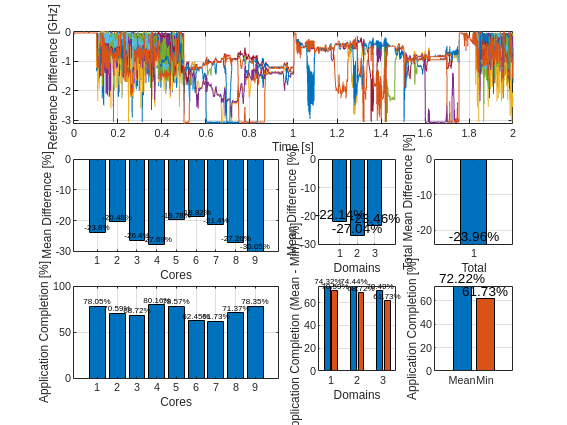

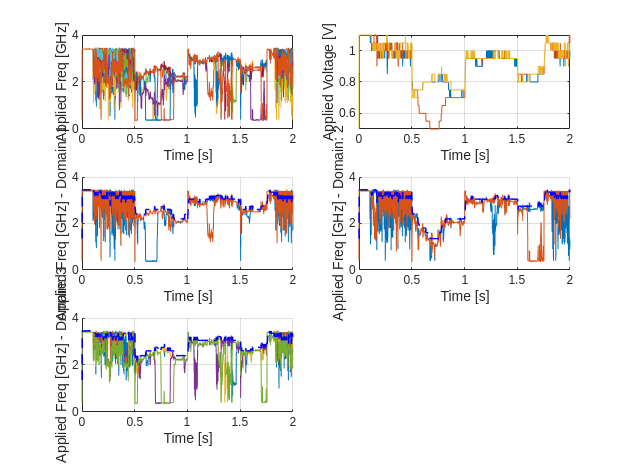

[CTRL][MPC] number of times the optimization algorithm failed:0/2000


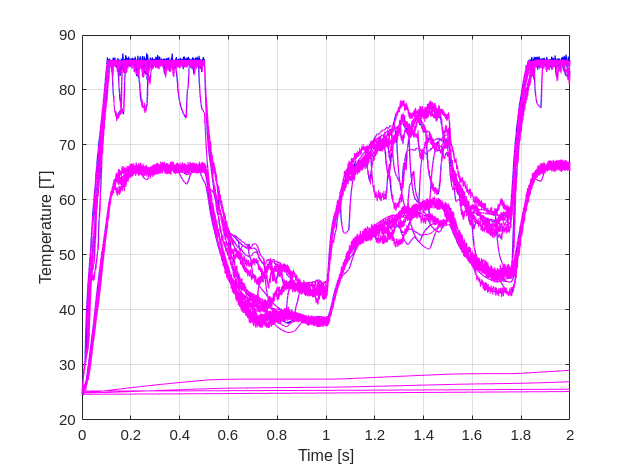

%Launch Simulation
tic;
hpc.simulation(ctrl,1);

toc;

Elapsed time is 14.740323 seconds.


## Warm Starting

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 95, constraints m = 97
          nnz(P) + nnz(A) = 1568
settings: linear system solver = qdldl,
          eps_abs = 1.0e-03, eps_rel = 1.0e-04,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 23
          check_termination: off,
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off

iter   objective    pri res    dua res    rho        time
   1   0.0000e+00   2.98e+05   2.98e+07   1.00e-01   5.59e-04s
  23   1.4543e-02   2.34e+02   3.92e+02   1.00e-01   1.10e-03s

status:               maximum iterations reached
number of i

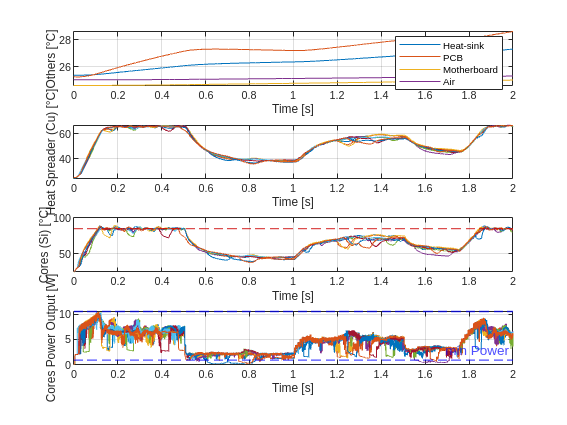

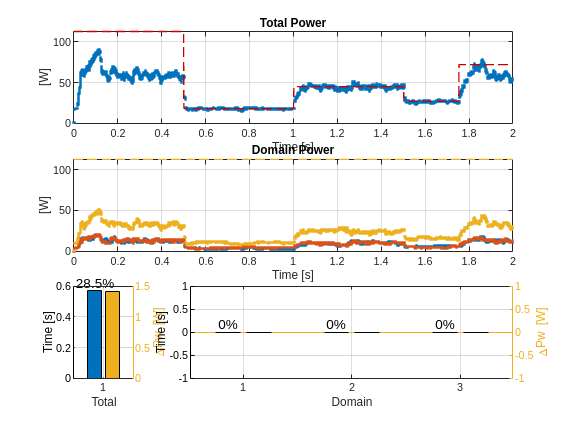

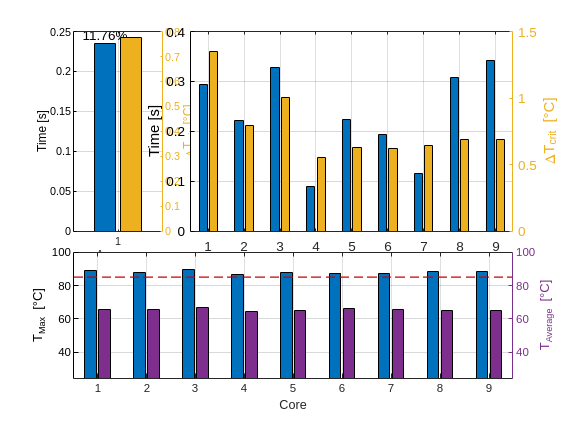

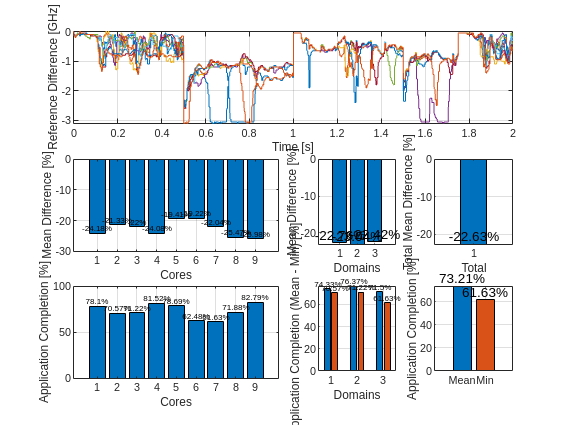

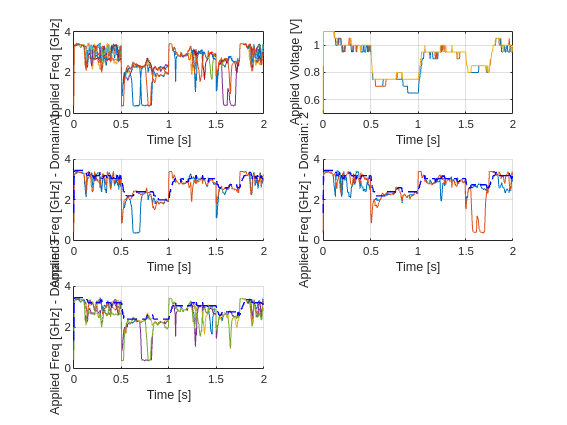

[CTRL][MPC] number of times the optimization algorithm failed:0/400


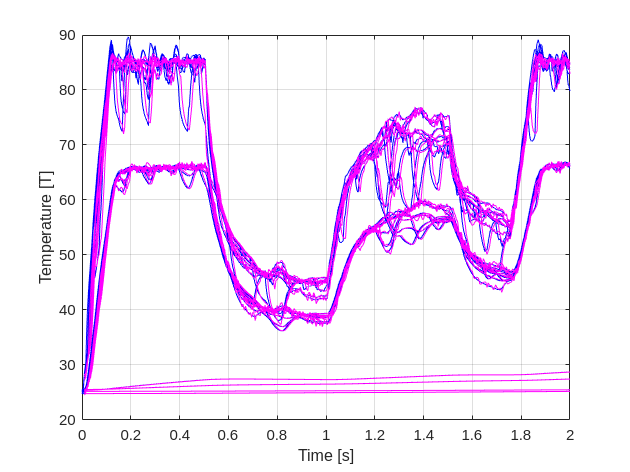

ctrl = cp_mpc;
set = osqp.default_settings;
set.warm_start = true;
set.verbose = true;
set.rho = 0.1;
set.eps_abs = 0.001; %0.01
set.eps_rel = 0.0001; %0.01
set.check_termination = 0;
set.max_iter = 7;
ctrl.ops = set;

ctrl.save_solver_stats = true; 
ctrl.C = eye(hpc.Ns);

%Controller frequency (s)
ctrl.Ts_ctrl = 5e-3;
ctrl.Nhzn = 2;

%Robust Margins for T and P
ctrl.Cty = zeros(ctrl.Nhzn, hpc.Nc);
ctrl.Ctu = zeros(ctrl.Nhzn, hpc.Nc);

%Reference Tracking Objective Matrix
R_coeff = 10;
ctrl.R = R_coeff*eye(hpc.Nc);

%Others
ctrl.R2 = zeros(hpc.Nc);
ctrl.Q = zeros(hpc.Ns);

%Launch Simulation
tic;
hpc.simulation(ctrl,1);

toc;

Elapsed time is 8.315778 seconds.


## Run Checks and Optain Metrics

% get primal variables from optimizer
prim = [ctrl.solver_stats.prim];
dual = [ctrl.solver_stats.dua];

pusum = prim(end,:);

u0ap = [ctrl.solver_stats.u0];
usum = [ctrl.solver_stats.usum];
uref = [ctrl.solver_stats.uref];
info = [ctrl.solver_stats.info];
lin  = [ctrl.solver_stats.lin];
uin  = [ctrl.solver_stats.uin];
iter = [info.iter];
pri_res = [info.pri_res];
dua_res = [info.dua_res];

% average primal and dual residual
mean(pri_res)
mean(dua_res)

% average rho estimate
rho_estimate = [info.rho_estimate];
mean(rho_estimate)
min(rho_estimate)
max(rho_estimate)
mean(iter)
min(iter)
max(iter)


% check constraints row by row
for i= 1:length(ctrl.mz.A)
    fprintf('row: %i: ',i);
    disp(ctrl.mz.A(i,:)); %display each row
end

'Checking that usum is applied in l, u:'
ctrl.mz.A(33,:)
max(max(lin(33,:)-usum))
max(max(lin(33,:)-usum))
'Checking that power budget constraint is satisfied:'
ctrl.mz.A(87,:)
ctrl.mz.A(97,:)

vec = ctrl.mz.A*prim;
time = 150;
applied = u0ap(:,time) % power we apply
sumapplied = sum(applied) % total power we apply
usumopt = prim(95,time) % sum power optimizer allocates 
usumconstr = usum(time) % input constraint
mismatch = vec(87,time)     % power sum constraint mismatch (dual)
umismatch = uin(87,time) % upper limit of mismatch
lmismatch = lin(87,time) % lower limit of mismatch
vec(87,:)<=uin(87,:) % all the time instances where power sum is violated